animate = true;
parameters_monoped;
side = -1; % 1 = front, -1 = back

grav = 9.81;

% lb = abs(Body.length_motor(1))/1000;
lf = Femur.length; lt = Tibia.length; lf_o = Femur.offset; lt_o = Tibia.offset;
lp = Piston.length/1000;

q0_val = out.q; T0_disp = out.T0; N = out.N;
u_val = zeros(3,N);
lambda = out.lambda_grf;

h = out.h;
t = 0;

for k = 1:N - 1
    t = [t;t(end) + h(k)];
end

% t = t0(1:end-1);
try
T1_disp = out.T1; N1_disp = out.N1; T2_disp = out.T2; N2_disp = out.N2;
t1 = full(linspace(T0_disp,T0_disp+T1_disp,N1_disp+1));
t2 = full(linspace(T0_disp+T1_disp,T0_disp+T1_disp+T2_disp,N2_disp+1));
t = [t0(1:end-1),t1(1:end-1),t2(1:end-1)];
catch
end

x = [q0_val(1,:)];
y = [q0_val(2,:)];
th = [q0_val(3,:)];
l = [q0_val(4,:)];
dx = [q0_val(5,:)];
dy = [q0_val(6,:)];
dth = [q0_val(7,:)];
dl = [q0_val(8,:)];
% x_osc = [q0_val(9,:)];
% y_osc = [q0_val(10,:)];
% Fe = [q0_val(11,:)];
% Fr = [q0_val(12,:)];

tau = u_val(1,:);
ue = u_val(2,:);
ur = u_val(3,:);

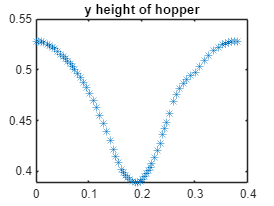

foot = zeros(4,length(t));
phi = zeros(1,length(t));
for i = 1:length(t)
    thk = thk_calc(th(i),l(i)); dthk = dthk_calc(th(i),l(i),dth(i),dl(i));
    tha = tha_calc(th(i),l(i)); dtha = dtha_calc(th(i),l(i),dth(i),dl(i));
    
    q_sys = num2cell(q0_val(1:end-2,i));

    foot(:,i) = foot_Func(q_sys{:});
    phi(i) = phi_calc(th(i),max(l(i),0));
end

q0_next = [];
% q1_next = [];
% q2_next = [];
% 
% param0_val = [0.1,tsw,0.1,T0_disp/N0_disp];
% param1_val = [0.1,tsw,0.1,T1/N1];
% param2_val = [0.1,tsw,0.1,T2/N2];

% Next Value
% for i = 1:N0
%     q_next = F_sys('x0',q0_val(:,i),'p',param0_val);
%     q0_next = [q0_next, full(q_next.xf)];
% end

% q_next = [q0_next];

figure;
plot(t,y,'*')
title('y height of hopper');

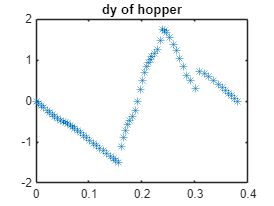


% hold on
% 
% plot(t(2:end),q_next(2,1:end-1),'r*');
% 
% hold off

figure;
plot(t,dy,'*')
title('dy of hopper');

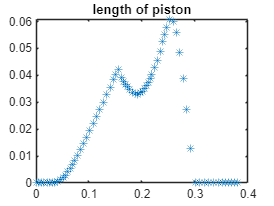


% hold on
% plot(t,y,'*')
% hold off

% figure;
% plot(t,foot(1,:),'*');
% title('x of foot');

figure;
plot(t,l,'*');
title('length of piston');

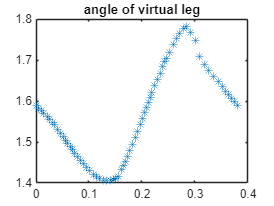


figure;
plot(t,phi,'*');
title('angle of virtual leg');

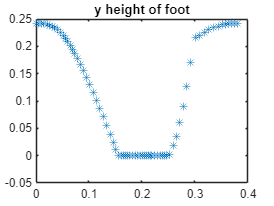


% figure;
% plot(t,tau,'*');
% title('torque');

figure;
plot(t,foot(2,:),'*');
title('y height of foot');

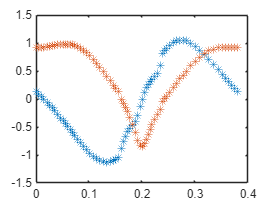


cpg = out.cpg;
figure;
plot(t,cpg(1,:),'*');
hold on;
plot(t,cpg(2,:),'*');
hold off

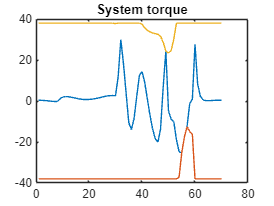


t_max = 38; %Nm
t_rated = 9.1; %Nm
w_max = 218/60*2*pi; %rad/s
w_rated = 177*2*pi/60; %rad/s
torque_max = min(((out.q(7,:)-w_max)*t_rated)/(w_rated-w_max), t_max);
torque_min = max(((out.q(7,:)+w_max)*t_rated)/(w_rated-w_max), -t_max);

figure;
plot(out.u(1,:));
hold on
plot(torque_min);
plot(torque_max);
title("System torque")
hold off

if animate
fps = 30; % Desired frame rate
dt = 1 / fps; % Time interval between frames
t_interp = t(1):dt:t(end); % New time vector

% Interpolate all states in sols.y
solsy_interp = interp1(t, q0_val', t_interp, 'linear')';

% x_sim = sols.y(1,:);
% y_sim = sols.y(2,:);
% th_sim = sols.y(3,:);
% l_sim = sols.y(4,:);
x_sim = solsy_interp(1,:);
y_sim = solsy_interp(2,:);
th_sim = solsy_interp(3,:);
l_sim = solsy_interp(4,:);
thk_sim = thk_calc(th_sim,l_sim);
tha_sim = tha_calc(th_sim,l_sim);

x_knee = x_sim - lf*cos(th_sim)*side;
y_knee = y_sim - lf*sin(th_sim);
x_foot = x_knee + lt*cos(thk_sim)*side;
y_foot = y_knee - lt*sin(thk_sim);

x_piston_top = x_sim + lf_o*sin(th_sim)*side;
y_piston_top = y_sim - lf_o*cos(th_sim);
x_piston_end = x_piston_top - lp*cos(tha_sim)*side;
y_piston_end = y_piston_top - lp*sin(tha_sim);
x_rod_end = x_piston_end - (l_sim).*cos(tha_sim)*side;
y_rod_end = y_piston_end - (l_sim).*sin(tha_sim);

% plot(y_foot)

Elapsed time is 3.375209 seconds.


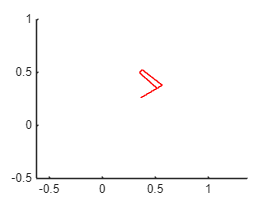

fig = figure;

ax = axes('Parent',fig);

b = animatedline(ax,'Color','b','LineWidth',1);
f = animatedline(ax,'Color','r','LineWidth',0.5);
t = animatedline(ax,'Color','r','LineWidth',0.5);
p_o = animatedline(ax,'Color','r','LineWidth',0.5);
p = animatedline(ax,'Color','r','LineWidth',0.5);
r = animatedline(ax,'Color','b','LineWidth',0.5);

axes(ax);

axis equal;
axis(ax,[(x_sim(1)-1) (x_sim(1)+1) -0.5 1]);

hold on;
tic
drawnow

for i = 1:width(solsy_interp)

    clearpoints(b);
    clearpoints(f);
    clearpoints(t);
    clearpoints(p_o);
    clearpoints(p);
    clearpoints(r);

    % axis equal;
    % axis([-1 11 -0.5 1]);
    % body
    addpoints(b,x_sim(i),y_sim(i));
    % femur
    addpoints(f,[x_sim(i), x_knee(i)],[y_sim(i), y_knee(i)]);
    % tibia
    addpoints(t,[x_knee(i), x_foot(i)],[y_knee(i), y_foot(i)]);
    % piston offset
    addpoints(p_o,[x_sim(i), x_piston_top(i)],[y_sim(i), y_piston_top(i)]);
    % piston
    addpoints(p,[x_piston_top(i), x_piston_end(i)],[y_piston_top(i), y_piston_end(i)]);
    % rod
    addpoints(r,[x_piston_end(i), x_rod_end(i)],[y_piston_end(i), y_rod_end(i)]);

    axis(ax,[(x_sim(i)-1) (x_sim(i)+1) -0.5 1]);

    drawnow
    pause(dt);

end
drawnow
toc
hold off;
end